***Definições Iniciais***

rng(7);
clear;
% Qtd de Seções delay = Qtd de Subportadoras
M=16;
% Qtd de Seções Doppler = Qtd de Slots de Tempo
N=16;
% Banda das Subportadoras
df=15e3;
% Duração de um bloco
dT=1/df;
% Portadora
fc=4e9;
% Resolução do Grid OTFS
delayResolution = 1/(M*df);
dopplerResolution = 1/(N*dT);
% Transformada de Fourier Discreta
Fn=dftmtx(N);
Fn=Fn/norm(Fn);
Fm=dftmtx(M);
Fm=Fm/norm(Fm);
%
c = physconst('Lightspeed');

***Prefixo Cíclico***

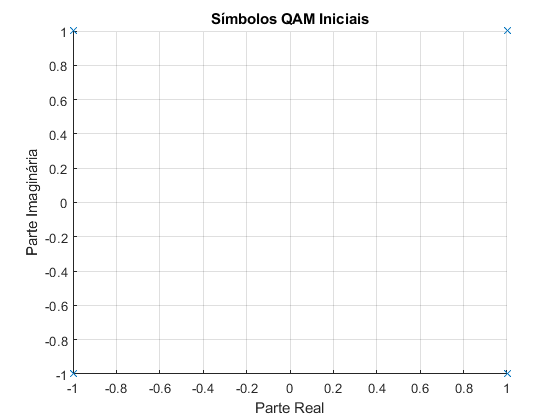

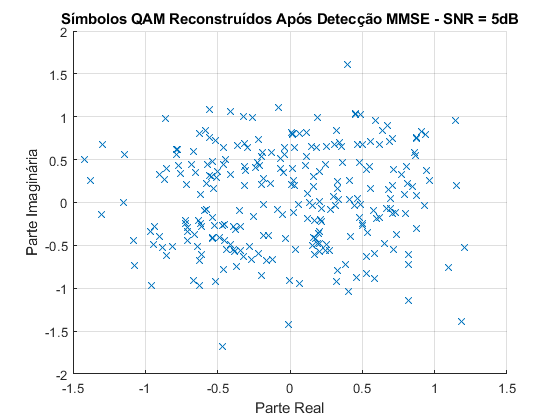

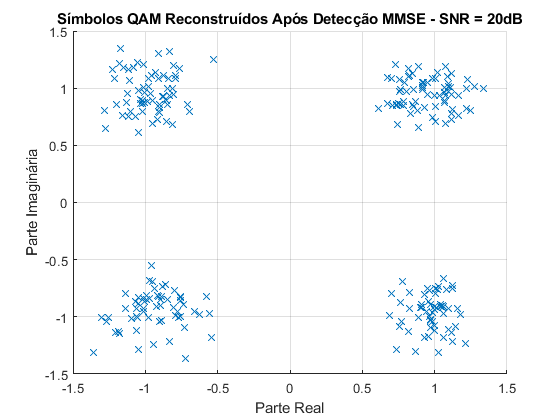

cpLength = M/4;

***BER EVA***

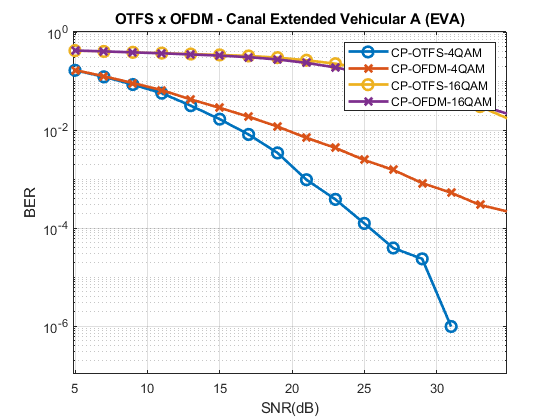

snr = 5:2:35;
qtyFrames = 2000;
SNR = 10.^(snr/10);
qtySyms4QAM = 4;
qtySyms16QAM = 16;

Es4QAM = mean(abs(qammod(0:qtySyms4QAM-1,qtySyms4QAM).^2));
sigma_2_4QAM = (abs(Es4QAM)^2)./SNR;
Es16QAM = mean(abs(qammod(0:qtySyms16QAM-1,qtySyms16QAM).^2));
sigma_2_16QAM = (abs(Es16QAM)^2)./SNR;

BER4QAM = zeros(3,length(snr));
meanBER4QAM = zeros(3,length(snr));
BER16QAM = zeros(2,length(snr));
meanBER16QAM = zeros(2,length(snr));

for snrIdx = 1:length(snr)
    for frameIdx = 1:qtyFrames
        qtySymsPerFrame=N*M;
        %Qtd de Bits por Frame
        qtyBitsPerFrame4QAM=qtySymsPerFrame*log2(qtySyms4QAM);
        %Geração dos bits p/ transmissão
        txBits4QAM=randi([0,1],qtyBitsPerFrame4QAM,1);
        %Bits em Símbolos - Código Gray
        txSyms4QAM=qammod(txBits4QAM,qtySyms4QAM,'gray','InputType','bit');
        %Matriz X de Símbolos
        X = reshape(txSyms4QAM,M,N);
        Xcp4QAM=reshape(txSyms4QAM,M,N);
        XcpOfdm4QAM=reshape(txSyms4QAM,M,N);
        
        %Qtd de Bits por Frame
        qtyBitsPerFrame16QAM=qtySymsPerFrame*log2(qtySyms16QAM);
        %Geração dos bits p/ transmissão
        txBits16QAM=randi([0,1],qtyBitsPerFrame16QAM,1);
        %Bits em Símbolos - Código Gray
        txSyms16QAM=qammod(txBits16QAM,qtySyms16QAM,'gray','InputType','bit');
        %Matriz X de Símbolos
        Xcp16QAM=reshape(txSyms16QAM,M,N);
        XcpOfdm16QAM=reshape(txSyms16QAM,M,N);
        
        %%%%%%%%%%%%%%%%% 4-QAM %%%%%%%%%%%%%%%%%%%%%%%%%
        %% OTFS %%
        %Aplicação ISFFT (OTFS) + DFT (OFDM)
        Xtil = X*Fn';
        XcpTil4QAM=Xcp4QAM*Fn';
        XcpTil4QAM = [XcpTil4QAM(end-cpLength+1:end,:); XcpTil4QAM];
        %Sinal a ser transmitido
        s=reshape(Xtil,1,N*M); 
        scp4QAM=reshape(XcpTil4QAM,1,N*(M+cpLength));
        
        %% OFDM %%
        XcpOfdmTil4QAM=Fm'*XcpOfdm4QAM;
        XcpOfdmTil4QAM = [XcpOfdmTil4QAM(end-cpLength+1:end,:); XcpOfdmTil4QAM];
        scpOfdm4QAM=reshape(XcpOfdmTil4QAM,1,N*(M+cpLength));
        
        %%%%%%%%%%%%%%%%% 16-QAM %%%%%%%%%%%%%%%%%%%%%%%%%
        %% OTFS %%
        %Aplicação ISFFT (OTFS) + DFT (OFDM)
        XcpTil16QAM=Xcp16QAM*Fn';
        XcpTil16QAM = [XcpTil16QAM(end-cpLength+1:end,:); XcpTil16QAM];
        %Sinal a ser transmitido
        scp16QAM=reshape(XcpTil16QAM,1,N*(M+cpLength));
        
        %% OFDM %%
        XcpOfdmTil16QAM=Fm'*XcpOfdm16QAM;
        XcpOfdmTil16QAM = [XcpOfdmTil16QAM(end-cpLength+1:end,:); XcpOfdmTil16QAM];
        scpOfdm16QAM=reshape(XcpOfdmTil16QAM,1,N*(M+cpLength));
        
        %% CANAL %%
        % EVA
        delaysChannel= [0, 30, 150, 310, 370, 710, 1090, 1730, 2510]*1e-9;
        dB = [0.0, -1.5, -1.4, -3.6, -0.6, -9.1, -7.0, -12.0, -16.9];
        % Vel. Máx. UE
        maxUEVelKmh=500;
        maxUEVel = maxUEVelKmh*1000*1/60*1/60;
        
        % Potência dB -> Linear normalizado
        linear = 10.^(dB/10);
        linear = linear/sum(linear);
        % Caminhos de propagação
        taps=length(delaysChannel);
        %Coeficientes de Ganho (Rayleigh fading)
        gains = sqrt(linear).*(sqrt(1/2) * (randn(1,taps)+1i*randn(1,taps)));
        %Coeficientes de Delay
        delays = round(delaysChannel./delayResolution);
        %Doppler Spread Máximo Normalizado
        nuMax = maxUEVel*fc/c;
        nuMax = nuMax/dopplerResolution;
        %Coeficientes de Doppler Shift (Jakes Spectrum)
        dopplerShifts = (nuMax*cos(2*pi*rand(1,taps)));
        %Delays distintos
        uniqueDelays = unique(delays);
        
        % Resposta ao Impulso Discreta - g^s
        gs=zeros(max(uniqueDelays)+1,N*(M+cpLength));
        for q=1:N*(M+cpLength)
          for i=1:taps
            gs(delays(i)+1,q)=gs(delays(i)+1,q)+gains(i)*z^(dopplerShifts(i)*((q-1) - delays(i)));
          end
        end
        
        % Matriz do Canal no Tempo - G
        G=zeros(N*M,N*M);
        for q=1:N*M
            for l=(uniqueDelays+1)
                if(q>=l)
                    G(q,q-l+1)=gs(l,q);
                end
            end
        end
        
        % Sinal ao atravessar o canal
        r=zeros(N*M,1);
        for q=1:N*M
            for l=(uniqueDelays+1)
                if(q>=l)
                    r(q)=r(q)+gs(l,q)*s(q-l+1);
                end
            end
        end
        
        rcp4QAM=zeros(N*(M+cpLength),1);
        rcpOfdm4QAM=zeros(N*(M+cpLength),1);
        
        rcp16QAM=zeros(N*(M+cpLength),1);
        rcpOfdm16QAM=zeros(N*(M+cpLength),1);
        
        for q=1:N*(M+cpLength)
          for l=(uniqueDelays+1)
            if(q>=l)
              rcp4QAM(q)=rcp4QAM(q)+gs(l,q)*scp4QAM(q-l+1);
              rcpOfdm4QAM(q)=rcpOfdm4QAM(q)+gs(l,q)*scpOfdm4QAM(q-l+1);
              
              rcp16QAM(q)=rcp16QAM(q)+gs(l,q)*scp16QAM(q-l+1);
              rcpOfdm16QAM(q)=rcpOfdm16QAM(q)+gs(l,q)*scpOfdm16QAM(q-l+1);
            end
          end
        end
        % Adicionar Ruído 
        
        noise = sqrt(sigma_2_4QAM(snrIdx)/2)*(randn(N*M,1) + 1i*randn(N*M,1));
        noise4QAM = sqrt(sigma_2_4QAM(snrIdx)/2)*(randn(N*(M+cpLength),1) + 1i*randn(N*(M+cpLength),1));
        noise16QAM = sqrt(sigma_2_16QAM(snrIdx)/2)*(randn(N*(M+cpLength),1) + 1i*randn(N*(M+cpLength),1));
        
        r = r + noise;
        
        rcp4QAM = rcp4QAM + noise4QAM;
        rcpOfdm4QAM = rcpOfdm4QAM + noise4QAM;
        
        rcp16QAM = rcp16QAM + noise16QAM;
        rcpOfdm16QAM = rcpOfdm16QAM + noise16QAM;
        
        %%%%%%%%%%%% DETECÇÃO MMSE - SEM CP %%%%%%%%%%%%%%
        % Regularização para evitar uma matriz não inversível
        lambda = 1e-9;
        A = G' * G + sigma_2_4QAM(snrIdx) * eye(size(G, 2));
        XtilHat = reshape((A + lambda * eye(size(A))) \ (G' * r), M, N);
        
        % Aplicação IDFT (OFDM) + SFFT (OTFS)
        Xhat = XtilHat*Fn;
        xHatSyms = reshape(Xhat,N*M,1);
        xHatBits = qamdemod(xHatSyms, qtySyms4QAM, 'gray', 'OutputType', 'bit');
        
        % Detecção Block-wise devido ao CP
        sn_block_est_cp_4QAM=zeros(M+cpLength,N);
        sn_block_est_cp_ofdm_4QAM=zeros(M+cpLength,N);
        
        sn_block_est_cp_16QAM=zeros(M+cpLength,N);
        sn_block_est_cp_ofdm_16QAM=zeros(M+cpLength,N);
        
        Gn=zeros(M+cpLength,M+cpLength);
        for n=1:N
            for m=1:M+cpLength
                for l=uniqueDelays+1
                    if(m>=l)
                        Gn(m,m-l+1)=gs(l,m+(n-1)*(M+cpLength));
                    end
                end
            end
            rncp4QAM=rcp4QAM((n-1)*(M+cpLength)+1:n*(M+cpLength));
            rncpOfdm4QAM=rcpOfdm4QAM((n-1)*(M+cpLength)+1:n*(M+cpLength));
            
            rncp16QAM=rcp16QAM((n-1)*(M+cpLength)+1:n*(M+cpLength));
            rncpOfdm16QAM=rcpOfdm16QAM((n-1)*(M+cpLength)+1:n*(M+cpLength));
            
            Rn=Gn'*Gn;
            
            sn_block_est_cp_4QAM(:,n)=(Rn+sigma_2_4QAM(snrIdx).*eye(M+cpLength))\(Gn'*rncp4QAM);
            sn_block_est_cp_ofdm_4QAM(:,n)=(Rn+sigma_2_4QAM(snrIdx).*eye(M+cpLength))\(Gn'*rncpOfdm4QAM);
            
            sn_block_est_cp_16QAM(:,n)=(Rn+sigma_2_16QAM(snrIdx).*eye(M+cpLength))\(Gn'*rncp16QAM);
            sn_block_est_cp_ofdm_16QAM(:,n)=(Rn+sigma_2_16QAM(snrIdx).*eye(M+cpLength))\(Gn'*rncpOfdm16QAM);
        end
        XcpTilHat4QAM=sn_block_est_cp_4QAM;
        XcpOfdmTilHat4QAM=sn_block_est_cp_ofdm_4QAM;
        
        XcpTilHat16QAM=sn_block_est_cp_16QAM;
        XcpOfdmTilHat16QAM=sn_block_est_cp_ofdm_16QAM;
        
        %%%%%%%%%%%%%%%%% 4 QAM %%%%%%%%%%%%%%%%%%%%%%%%%%
        %% OTFS %%
        % Aplicação IDFT (OFDM) + SFFT (OTFS)
        XcpHat4QAM = XcpTilHat4QAM*Fn;
        XcpHatData4QAM = XcpHat4QAM(cpLength+1:end, :);
        xcpHat4QAM = reshape(XcpHatData4QAM,N*M,1);
        xcpHatBits4QAM = qamdemod(xcpHat4QAM, qtySyms4QAM, 'gray', 'OutputType', 'bit');
        
        %% OFDM %%
        XcpOfdmTilHatData4QAM = XcpOfdmTilHat4QAM(cpLength+1:end, :);
        XcpOfdmHatData4QAM = Fm*XcpOfdmTilHatData4QAM;
        xcpOfdmHat4QAM = reshape(XcpOfdmHatData4QAM,N*M,1);
        xcpOfdmHatBits4QAM = qamdemod(xcpOfdmHat4QAM, qtySyms4QAM, 'gray', 'OutputType', 'bit');
        
        %%%%%%%%%%%%%%%%% 16 QAM %%%%%%%%%%%%%%%%%%%%%%%%%%
        %% OTFS %%
        % Aplicação IDFT (OFDM) + SFFT (OTFS)
        XcpHat16QAM = XcpTilHat16QAM*Fn;
        XcpHatData16QAM = XcpHat16QAM(cpLength+1:end, :);
        xcpHat16QAM = reshape(XcpHatData16QAM,N*M,1);
        xcpHatBits16QAM = qamdemod(xcpHat16QAM, qtySyms16QAM, 'gray', 'OutputType', 'bit');
        
        %% OFDM %%
        XcpOfdmTilHatData16QAM = XcpOfdmTilHat16QAM(cpLength+1:end, :);
        XcpOfdmHatData16QAM= Fm*XcpOfdmTilHatData16QAM;
        xcpOfdmHat16QAM = reshape(XcpOfdmHatData16QAM,N*M,1);
        xcpOfdmHatBits16QAM = qamdemod(xcpOfdmHat16QAM, qtySyms16QAM, 'gray', 'OutputType', 'bit');
             
        %BER
        err = sum(xHatBits ~= txBits4QAM);
        
        errcp4QAM = sum(xcpHatBits4QAM ~= txBits4QAM);
        errcpOfdm4QAM = sum(xcpOfdmHatBits4QAM ~= txBits4QAM);
               
        BER4QAM(3,snrIdx) = BER4QAM(3,snrIdx) + err;
        meanBER4QAM(3,snrIdx) = BER4QAM(3,snrIdx)*1/length(txBits4QAM)*1/frameIdx;
        
        BER4QAM(1,snrIdx) = BER4QAM(1,snrIdx) + errcp4QAM;
        meanBER4QAM(1,snrIdx) = BER4QAM(1,snrIdx)*1/length(txBits4QAM)*1/frameIdx;
        BER4QAM(2,snrIdx) = BER4QAM(2,snrIdx) + errcpOfdm4QAM;
        meanBER4QAM(2,snrIdx) = BER4QAM(2,snrIdx)*1/length(txBits4QAM)*1/frameIdx;
        
        errcp16QAM = sum(xcpHatBits16QAM ~= txBits16QAM);
        errcpOfdm16QAM = sum(xcpOfdmHatBits16QAM ~= txBits16QAM); 
        
        BER16QAM(1,snrIdx) = BER16QAM(1,snrIdx) + errcp16QAM;
        meanBER16QAM(1,snrIdx) = BER16QAM(1,snrIdx)*1/length(txBits16QAM)*1/frameIdx;
        BER16QAM(2,snrIdx) = BER16QAM(2,snrIdx) + errcpOfdm16QAM;
        meanBER16QAM(2,snrIdx) = BER16QAM(2,snrIdx)*1/length(txBits16QAM)*1/frameIdx;
    end 
end

semilogy(snr,meanBER4QAM(1,:),'o-','LineWidth',2,'MarkerSize',8)
hold on;
semilogy(snr,meanBER4QAM(2,:),'x-','LineWidth',2,'MarkerSize',8)
hold on;
semilogy(snr,meanBER16QAM(1,:),'o-','LineWidth',2,'MarkerSize',8)
hold on;
semilogy(snr,meanBER16QAM(2,:),'x-','LineWidth',2,'MarkerSize',8)
hold on;
grid on
xlabel('SNR(dB)')
ylabel('BER')
title('OTFS x OFDM - Canal Extended Vehicular A (EVA)')

legend('CP-OTFS-4QAM', 'CP-OFDM-4QAM', 'CP-OTFS-16QAM', 'CP-OFDM-16QAM');
hold off;

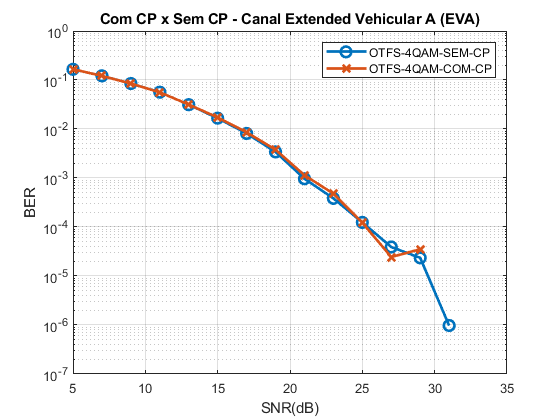


semilogy(snr,meanBER4QAM(1,:),'o-','LineWidth',2,'MarkerSize',8)
hold on;
semilogy(snr,meanBER4QAM(3,:),'x-','LineWidth',2,'MarkerSize',8)
hold on;
grid on
xlabel('SNR(dB)')
ylabel('BER')
title('Com CP x Sem CP - Canal Extended Vehicular A (EVA)')

legend('OTFS-4QAM-SEM-CP', 'OTFS-4QAM-COM-CP');
hold off;

***BER EPA***

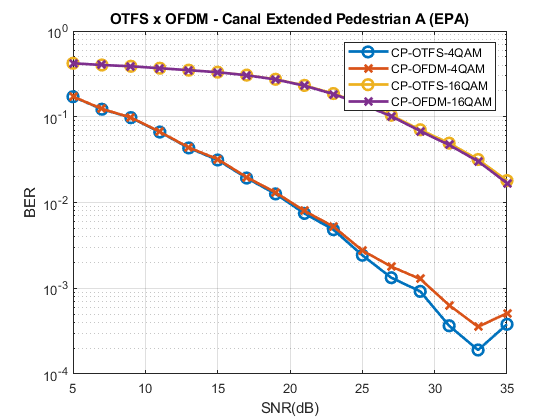

snr = 5:2:35;
qtyFrames = 2000;
SNR = 10.^(snr/10);
qtySyms4QAM = 4;
qtySyms16QAM = 16;

Es4QAM = mean(abs(qammod(0:qtySyms4QAM-1,qtySyms4QAM).^2));
sigma_2_4QAM = (abs(Es4QAM)^2)./SNR;
Es16QAM = mean(abs(qammod(0:qtySyms16QAM-1,qtySyms16QAM).^2));
sigma_2_16QAM = (abs(Es16QAM)^2)./SNR;

BER4QAM = zeros(3,length(snr));
meanBER4QAM = zeros(3,length(snr));
BER16QAM = zeros(2,length(snr));
meanBER16QAM = zeros(2,length(snr));

for snrIdx = 1:length(snr)
    for frameIdx = 1:qtyFrames
        qtySymsPerFrame=N*M;
        %Qtd de Bits por Frame
        qtyBitsPerFrame4QAM=qtySymsPerFrame*log2(qtySyms4QAM);
        %Geração dos bits p/ transmissão
        txBits4QAM=randi([0,1],qtyBitsPerFrame4QAM,1);
        %Bits em Símbolos - Código Gray
        txSyms4QAM=qammod(txBits4QAM,qtySyms4QAM,'gray','InputType','bit');
        %Matriz X de Símbolos
        X = reshape(txSyms4QAM,M,N);
        Xcp4QAM=reshape(txSyms4QAM,M,N);
        XcpOfdm4QAM=reshape(txSyms4QAM,M,N);
        
        %Qtd de Bits por Frame
        qtyBitsPerFrame16QAM=qtySymsPerFrame*log2(qtySyms16QAM);
        %Geração dos bits p/ transmissão
        txBits16QAM=randi([0,1],qtyBitsPerFrame16QAM,1);
        %Bits em Símbolos - Código Gray
        txSyms16QAM=qammod(txBits16QAM,qtySyms16QAM,'gray','InputType','bit');
        %Matriz X de Símbolos
        Xcp16QAM=reshape(txSyms16QAM,M,N);
        XcpOfdm16QAM=reshape(txSyms16QAM,M,N);
        
        %%%%%%%%%%%%%%%%% 4-QAM %%%%%%%%%%%%%%%%%%%%%%%%%
        %% OTFS %%
        %Aplicação ISFFT (OTFS) + DFT (OFDM)
        Xtil = X*Fn';
        XcpTil4QAM=Xcp4QAM*Fn';
        XcpTil4QAM = [XcpTil4QAM(end-cpLength+1:end,:); XcpTil4QAM];
        %Sinal a ser transmitido
        s=reshape(Xtil,1,N*M); 
        scp4QAM=reshape(XcpTil4QAM,1,N*(M+cpLength));
        
        %% OFDM %%
        XcpOfdmTil4QAM=Fm'*XcpOfdm4QAM;
        XcpOfdmTil4QAM = [XcpOfdmTil4QAM(end-cpLength+1:end,:); XcpOfdmTil4QAM];
        scpOfdm4QAM=reshape(XcpOfdmTil4QAM,1,N*(M+cpLength));
        
        %%%%%%%%%%%%%%%%% 16-QAM %%%%%%%%%%%%%%%%%%%%%%%%%
        %% OTFS %%
        %Aplicação ISFFT (OTFS) + DFT (OFDM)
        XcpTil16QAM=Xcp16QAM*Fn';
        XcpTil16QAM = [XcpTil16QAM(end-cpLength+1:end,:); XcpTil16QAM];
        %Sinal a ser transmitido
        scp16QAM=reshape(XcpTil16QAM,1,N*(M+cpLength));
        
        %% OFDM %%
        XcpOfdmTil16QAM=Fm'*XcpOfdm16QAM;
        XcpOfdmTil16QAM = [XcpOfdmTil16QAM(end-cpLength+1:end,:); XcpOfdmTil16QAM];
        scpOfdm16QAM=reshape(XcpOfdmTil16QAM,1,N*(M+cpLength));
        
        %% CANAL %%
        % EPA
        delaysChannel = [0, 30, 70, 90, 110, 190, 410]*1e-9;
        dB = [0.0, -1.0, -2.0, -3.0, -8.0, -17.2, -20.8];
        % Vel. Máx. UE
        maxUEVelKmh=20;
        maxUEVel = maxUEVelKmh*1000*1/60*1/60;
        
        % Potência dB -> Linear normalizado
        linear = 10.^(dB/10);
        linear = linear/sum(linear);
        % Caminhos de propagação
        taps=length(delaysChannel);
        %Coeficientes de Ganho (Rayleigh fading)
        gains = sqrt(linear).*(sqrt(1/2) * (randn(1,taps)+1i*randn(1,taps)));
        %Coeficientes de Delay
        delays = round(delaysChannel./delayResolution);
        %Doppler Spread Máximo Normalizado
        nuMax = maxUEVel*fc/c;
        nuMax = nuMax/dopplerResolution;
        %Coeficientes de Doppler Shift (Jakes Spectrum)
        dopplerShifts = (nuMax*cos(2*pi*rand(1,taps)));
        %Delays distintos
        uniqueDelays = unique(delays);
        
        % Resposta ao Impulso Discreta - g^s
        gs=zeros(max(uniqueDelays)+1,N*(M+cpLength));
        for q=1:N*(M+cpLength)
          for i=1:taps
            gs(delays(i)+1,q)=gs(delays(i)+1,q)+gains(i)*z^(dopplerShifts(i)*((q-1) - delays(i)));
          end
        end
        
        % Matriz do Canal no Tempo - G
        G=zeros(N*M,N*M);
        for q=1:N*M
            for l=(uniqueDelays+1)
                if(q>=l)
                    G(q,q-l+1)=gs(l,q);
                end
            end
        end
        
        % Sinal ao atravessar o canal
        r=zeros(N*M,1);
        for q=1:N*M
            for l=(uniqueDelays+1)
                if(q>=l)
                    r(q)=r(q)+gs(l,q)*s(q-l+1);
                end
            end
        end
        
        rcp4QAM=zeros(N*(M+cpLength),1);
        rcpOfdm4QAM=zeros(N*(M+cpLength),1);
        
        rcp16QAM=zeros(N*(M+cpLength),1);
        rcpOfdm16QAM=zeros(N*(M+cpLength),1);
        
        for q=1:N*(M+cpLength)
          for l=(uniqueDelays+1)
            if(q>=l)
              rcp4QAM(q)=rcp4QAM(q)+gs(l,q)*scp4QAM(q-l+1);
              rcpOfdm4QAM(q)=rcpOfdm4QAM(q)+gs(l,q)*scpOfdm4QAM(q-l+1);
              
              rcp16QAM(q)=rcp16QAM(q)+gs(l,q)*scp16QAM(q-l+1);
              rcpOfdm16QAM(q)=rcpOfdm16QAM(q)+gs(l,q)*scpOfdm16QAM(q-l+1);
            end
          end
        end
        
        % Adicionar ruído
        noise = sqrt(sigma_2_4QAM(snrIdx)/2)*(randn(N*M,1) + 1i*randn(N*M,1));
        noise4QAM = sqrt(sigma_2_4QAM(snrIdx)/2)*(randn(N*(M+cpLength),1) + 1i*randn(N*(M+cpLength),1));
        noise16QAM = sqrt(sigma_2_16QAM(snrIdx)/2)*(randn(N*(M+cpLength),1) + 1i*randn(N*(M+cpLength),1));
        
        r = r + noise;
        
        rcp4QAM = rcp4QAM + noise4QAM;
        rcpOfdm4QAM = rcpOfdm4QAM + noise4QAM;
        
        rcp16QAM = rcp16QAM + noise16QAM;
        rcpOfdm16QAM = rcpOfdm16QAM + noise16QAM;
        
        %%%%%%%%%%%% DETECÇÃO MMSE - SEM CP %%%%%%%%%%%%%%
        % Regularização para evitar uma matriz não inversível
        lambda = 1e-9;
        A = G' * G + sigma_2_4QAM(snrIdx) * eye(size(G, 2));
        XtilHat = reshape((A + lambda * eye(size(A))) \ (G' * r), M, N);

        % Aplicação IDFT (OFDM) + SFFT (OTFS)
        Xhat = XtilHat*Fn;
        xHatSyms = reshape(Xhat,N*M,1);
        xHatBits = qamdemod(xHatSyms, qtySyms4QAM, 'gray', 'OutputType', 'bit');
        
        % Detecção Block-wise devido ao CP
        sn_block_est_cp_4QAM=zeros(M+cpLength,N);
        sn_block_est_cp_ofdm_4QAM=zeros(M+cpLength,N);
        
        sn_block_est_cp_16QAM=zeros(M+cpLength,N);
        sn_block_est_cp_ofdm_16QAM=zeros(M+cpLength,N);
        
        Gn=zeros(M+cpLength,M+cpLength);
        
        for n=1:N
            for m=1:M+cpLength
                for l=uniqueDelays+1
                    if(m>=l)
                        Gn(m,m-l+1)=gs(l,m+(n-1)*(M+cpLength));
                    end
                end
            end
            rncp4QAM=rcp4QAM((n-1)*(M+cpLength)+1:n*(M+cpLength));
            rncpOfdm4QAM=rcpOfdm4QAM((n-1)*(M+cpLength)+1:n*(M+cpLength));
            
            rncp16QAM=rcp16QAM((n-1)*(M+cpLength)+1:n*(M+cpLength));
            rncpOfdm16QAM=rcpOfdm16QAM((n-1)*(M+cpLength)+1:n*(M+cpLength));
            
            Rn=Gn'*Gn;
            
            sn_block_est_cp_4QAM(:,n)=(Rn+sigma_2_4QAM(snrIdx).*eye(M+cpLength))\(Gn'*rncp4QAM);
            sn_block_est_cp_ofdm_4QAM(:,n)=(Rn+sigma_2_4QAM(snrIdx).*eye(M+cpLength))\(Gn'*rncpOfdm4QAM);
            
            sn_block_est_cp_16QAM(:,n)=(Rn+sigma_2_16QAM(snrIdx).*eye(M+cpLength))\(Gn'*rncp16QAM);
            sn_block_est_cp_ofdm_16QAM(:,n)=(Rn+sigma_2_16QAM(snrIdx).*eye(M+cpLength))\(Gn'*rncpOfdm16QAM);
        end
        XcpTilHat4QAM=sn_block_est_cp_4QAM;
        XcpOfdmTilHat4QAM=sn_block_est_cp_ofdm_4QAM;
        
        XcpTilHat16QAM=sn_block_est_cp_16QAM;
        XcpOfdmTilHat16QAM=sn_block_est_cp_ofdm_16QAM;
        
        %%%%%%%%%%%%%%%%% 4 QAM %%%%%%%%%%%%%%%%%%%%%%%%%%
        %% OTFS %%
        % Aplicação IDFT (OFDM) + SFFT (OTFS)
        XcpHat4QAM = XcpTilHat4QAM*Fn;
        XcpHatData4QAM = XcpHat4QAM(cpLength+1:end, :);
        xcpHat4QAM = reshape(XcpHatData4QAM,N*M,1);
        xcpHatBits4QAM = qamdemod(xcpHat4QAM, qtySyms4QAM, 'gray', 'OutputType', 'bit');
        
        %% OFDM %%
        XcpOfdmTilHatData4QAM = XcpOfdmTilHat4QAM(cpLength+1:end, :);
        XcpOfdmHatData4QAM = Fm*XcpOfdmTilHatData4QAM;
        xcpOfdmHat4QAM = reshape(XcpOfdmHatData4QAM,N*M,1);
        xcpOfdmHatBits4QAM = qamdemod(xcpOfdmHat4QAM, qtySyms4QAM, 'gray', 'OutputType', 'bit');
        
        %%%%%%%%%%%%%%%%% 16 QAM %%%%%%%%%%%%%%%%%%%%%%%%%%
        %% OTFS %%
        % Aplicação IDFT (OFDM) + SFFT (OTFS)
        XcpHat16QAM = XcpTilHat16QAM*Fn;
        XcpHatData16QAM = XcpHat16QAM(cpLength+1:end, :);
        xcpHat16QAM = reshape(XcpHatData16QAM,N*M,1);
        xcpHatBits16QAM = qamdemod(xcpHat16QAM, qtySyms16QAM, 'gray', 'OutputType', 'bit');
        
        %% OFDM %%
        XcpOfdmTilHatData16QAM = XcpOfdmTilHat16QAM(cpLength+1:end, :);
        XcpOfdmHatData16QAM= Fm*XcpOfdmTilHatData16QAM;
        xcpOfdmHat16QAM = reshape(XcpOfdmHatData16QAM,N*M,1);
        xcpOfdmHatBits16QAM = qamdemod(xcpOfdmHat16QAM, qtySyms16QAM, 'gray', 'OutputType', 'bit');
             
        %BER
        err = sum(xHatBits ~= txBits4QAM);
        
        errcp4QAM = sum(xcpHatBits4QAM ~= txBits4QAM);
        errcpOfdm4QAM = sum(xcpOfdmHatBits4QAM ~= txBits4QAM);
               
        BER4QAM(3,snrIdx) = BER4QAM(3,snrIdx) + err;
        meanBER4QAM(3,snrIdx) = BER4QAM(3,snrIdx)*1/length(txBits4QAM)*1/frameIdx;
        
        BER4QAM(1,snrIdx) = BER4QAM(1,snrIdx) + errcp4QAM;
        meanBER4QAM(1,snrIdx) = BER4QAM(1,snrIdx)*1/length(txBits4QAM)*1/frameIdx;
        BER4QAM(2,snrIdx) = BER4QAM(2,snrIdx) + errcpOfdm4QAM;
        meanBER4QAM(2,snrIdx) = BER4QAM(2,snrIdx)*1/length(txBits4QAM)*1/frameIdx;
        
        errcp16QAM = sum(xcpHatBits16QAM ~= txBits16QAM);
        errcpOfdm16QAM = sum(xcpOfdmHatBits16QAM ~= txBits16QAM); 
        
        BER16QAM(1,snrIdx) = BER16QAM(1,snrIdx) + errcp16QAM;
        meanBER16QAM(1,snrIdx) = BER16QAM(1,snrIdx)*1/length(txBits16QAM)*1/frameIdx;
        BER16QAM(2,snrIdx) = BER16QAM(2,snrIdx) + errcpOfdm16QAM;
        meanBER16QAM(2,snrIdx) = BER16QAM(2,snrIdx)*1/length(txBits16QAM)*1/frameIdx;
    end 
end

semilogy(snr,meanBER4QAM(1,:),'o-','LineWidth',2,'MarkerSize',8)
hold on;
semilogy(snr,meanBER4QAM(2,:),'x-','LineWidth',2,'MarkerSize',8)
hold on;
semilogy(snr,meanBER16QAM(1,:),'o-','LineWidth',2,'MarkerSize',8)
hold on;
semilogy(snr,meanBER16QAM(2,:),'x-','LineWidth',2,'MarkerSize',8)
hold on;
grid on
xlabel('SNR(dB)')
ylabel('BER')
title('OTFS x OFDM - Canal Extended Pedestrian A (EPA)')

legend('CP-OTFS-4QAM', 'CP-OFDM-4QAM', 'CP-OTFS-16QAM', 'CP-OFDM-16QAM');
hold off;

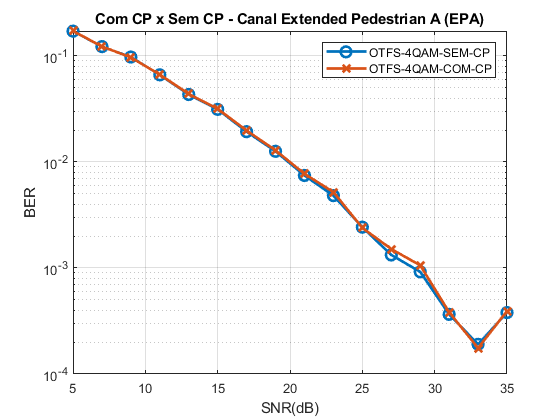



semilogy(snr,meanBER4QAM(1,:),'o-','LineWidth',2,'MarkerSize',8)
hold on;
semilogy(snr,meanBER4QAM(3,:),'x-','LineWidth',2,'MarkerSize',8)
hold on;
grid on
xlabel('SNR(dB)')
ylabel('BER')
title('Com CP x Sem CP - Canal Extended Pedestrian A (EPA)')

legend('OTFS-4QAM-SEM-CP', 'OTFS-4QAM-COM-CP');
hold off;

***BER ETU***

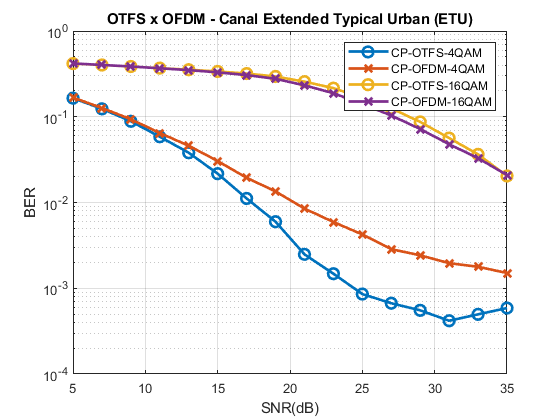

snr = 5:2:35;
qtyFrames = 2000;
SNR = 10.^(snr/10);
qtySyms4QAM = 4;
qtySyms16QAM = 16;

Es4QAM = mean(abs(qammod(0:qtySyms4QAM-1,qtySyms4QAM).^2));
sigma_2_4QAM = (abs(Es4QAM)^2)./SNR;
Es16QAM = mean(abs(qammod(0:qtySyms16QAM-1,qtySyms16QAM).^2));
sigma_2_16QAM = (abs(Es16QAM)^2)./SNR;

BER4QAM = zeros(3,length(snr));
meanBER4QAM = zeros(3,length(snr));
BER16QAM = zeros(2,length(snr));
meanBER16QAM = zeros(2,length(snr));

for snrIdx = 1:length(snr)
    for frameIdx = 1:qtyFrames
        qtySymsPerFrame=N*M;
        %Qtd de Bits por Frame
        qtyBitsPerFrame4QAM=qtySymsPerFrame*log2(qtySyms4QAM);
        %Geração dos bits p/ transmissão
        txBits4QAM=randi([0,1],qtyBitsPerFrame4QAM,1);
        %Bits em Símbolos - Código Gray
        txSyms4QAM=qammod(txBits4QAM,qtySyms4QAM,'gray','InputType','bit');
        %Matriz X de Símbolos
        X = reshape(txSyms4QAM,M,N);
        Xcp4QAM=reshape(txSyms4QAM,M,N);
        XcpOfdm4QAM=reshape(txSyms4QAM,M,N);
        
        %Qtd de Bits por Frame
        qtyBitsPerFrame16QAM=qtySymsPerFrame*log2(qtySyms16QAM);
        %Geração dos bits p/ transmissão
        txBits16QAM=randi([0,1],qtyBitsPerFrame16QAM,1);
        %Bits em Símbolos - Código Gray
        txSyms16QAM=qammod(txBits16QAM,qtySyms16QAM,'gray','InputType','bit');
        %Matriz X de Símbolos
        Xcp16QAM=reshape(txSyms16QAM,M,N);
        XcpOfdm16QAM=reshape(txSyms16QAM,M,N);
        
        %%%%%%%%%%%%%%%%% 4-QAM %%%%%%%%%%%%%%%%%%%%%%%%%
        %% OTFS %%
        %Aplicação ISFFT (OTFS) + DFT (OFDM)
        Xtil = X*Fn';
        XcpTil4QAM=Xcp4QAM*Fn';
        XcpTil4QAM = [XcpTil4QAM(end-cpLength+1:end,:); XcpTil4QAM];
        %Sinal a ser transmitido
        s=reshape(Xtil,1,N*M); 
        scp4QAM=reshape(XcpTil4QAM,1,N*(M+cpLength));
        
        %% OFDM %%
        XcpOfdmTil4QAM=Fm'*XcpOfdm4QAM;
        XcpOfdmTil4QAM = [XcpOfdmTil4QAM(end-cpLength+1:end,:); XcpOfdmTil4QAM];
        scpOfdm4QAM=reshape(XcpOfdmTil4QAM,1,N*(M+cpLength));
        
        %%%%%%%%%%%%%%%%% 16-QAM %%%%%%%%%%%%%%%%%%%%%%%%%
        %% OTFS %%
        %Aplicação ISFFT (OTFS) + DFT (OFDM)
        XcpTil16QAM=Xcp16QAM*Fn';
        XcpTil16QAM = [XcpTil16QAM(end-cpLength+1:end,:); XcpTil16QAM];
        %Sinal a ser transmitido
        scp16QAM=reshape(XcpTil16QAM,1,N*(M+cpLength));
        
        %% OFDM %%
        XcpOfdmTil16QAM=Fm'*XcpOfdm16QAM;
        XcpOfdmTil16QAM = [XcpOfdmTil16QAM(end-cpLength+1:end,:); XcpOfdmTil16QAM];
        scpOfdm16QAM=reshape(XcpOfdmTil16QAM,1,N*(M+cpLength));
        
        %% CANAL %%
        % EVA
        delaysChannel = [0, 50, 120, 200, 230, 500, 1600, 2300, 5000]*1e-9;
        dB = [-1.0, -1.0, -1.0, 0.0, 0.0, 0.0, -3.0, -5.0, -7.0];
        % Vel. Máx. UE
        maxUEVelKmh=100;
        maxUEVel = maxUEVelKmh*1000*1/60*1/60;
        
        % Potência dB -> Linear normalizado
        linear = 10.^(dB/10);
        linear = linear/sum(linear);
        % Caminhos de propagação
        taps=length(delaysChannel);
        %Coeficientes de Ganho (Rayleigh fading)
        gains = sqrt(linear).*(sqrt(1/2) * (randn(1,taps)+1i*randn(1,taps)));
        %Coeficientes de Delay
        delays = round(delaysChannel./delayResolution);
        %Doppler Spread Máximo Normalizado
        nuMax = maxUEVel*fc/c;
        nuMax = nuMax/dopplerResolution;
        %Coeficientes de Doppler Shift (Jakes Spectrum)
        dopplerShifts = (nuMax*cos(2*pi*rand(1,taps)));
        %Delays distintos
        uniqueDelays = unique(delays);
        
        % Resposta ao Impulso Discreta - g^s
        gs=zeros(max(uniqueDelays)+1,N*(M+cpLength));
        for q=1:N*(M+cpLength)
          for i=1:taps
            gs(delays(i)+1,q)=gs(delays(i)+1,q)+gains(i)*z^(dopplerShifts(i)*((q-1) - delays(i)));
          end
        end
        
        % Matriz do Canal no Tempo - G
        G=zeros(N*M,N*M);
        for q=1:N*M
            for l=(uniqueDelays+1)
                if(q>=l)
                    G(q,q-l+1)=gs(l,q);
                end
            end
        end
        
        % Sinal ao atravessar o canal
        r=zeros(N*M,1);
        for q=1:N*M
            for l=(uniqueDelays+1)
                if(q>=l)
                    r(q)=r(q)+gs(l,q)*s(q-l+1);
                end
            end
        end
        
        rcp4QAM=zeros(N*(M+cpLength),1);
        rcpOfdm4QAM=zeros(N*(M+cpLength),1);
        
        rcp16QAM=zeros(N*(M+cpLength),1);
        rcpOfdm16QAM=zeros(N*(M+cpLength),1);
        
        for q=1:N*(M+cpLength)
          for l=(uniqueDelays+1)
            if(q>=l)
              rcp4QAM(q)=rcp4QAM(q)+gs(l,q)*scp4QAM(q-l+1);
              rcpOfdm4QAM(q)=rcpOfdm4QAM(q)+gs(l,q)*scpOfdm4QAM(q-l+1);
              
              rcp16QAM(q)=rcp16QAM(q)+gs(l,q)*scp16QAM(q-l+1);
              rcpOfdm16QAM(q)=rcpOfdm16QAM(q)+gs(l,q)*scpOfdm16QAM(q-l+1);
            end
          end
        end
        noise = sqrt(sigma_2_4QAM(snrIdx)/2)*(randn(N*M,1) + 1i*randn(N*M,1));
        noise4QAM = sqrt(sigma_2_4QAM(snrIdx)/2)*(randn(N*(M+cpLength),1) + 1i*randn(N*(M+cpLength),1));
        noise16QAM = sqrt(sigma_2_16QAM(snrIdx)/2)*(randn(N*(M+cpLength),1) + 1i*randn(N*(M+cpLength),1));
        
        r = r + noise;
        
        rcp4QAM = rcp4QAM + noise4QAM;
        rcpOfdm4QAM = rcpOfdm4QAM + noise4QAM;
        
        rcp16QAM = rcp16QAM + noise16QAM;
        rcpOfdm16QAM = rcpOfdm16QAM + noise16QAM;
        
        %%%%%%%%%%%% DETECÇÃO MMSE - SEM CP %%%%%%%%%%%%%%
        % Regularização para evitar uma matriz não inversível
        lambda = 1e-9;
        A = G' * G + sigma_2_4QAM(snrIdx) * eye(size(G, 2));
        XtilHat = reshape((A + lambda * eye(size(A))) \ (G' * r), M, N);
        
        % Aplicação IDFT (OFDM) + SFFT (OTFS)
        Xhat = XtilHat*Fn;
        xHatSyms = reshape(Xhat,N*M,1);
        xHatBits = qamdemod(xHatSyms, qtySyms4QAM, 'gray', 'OutputType', 'bit');
        
        % Detecção Block-wise devido ao CP 
        sn_block_est_cp_4QAM=zeros(M+cpLength,N);
        sn_block_est_cp_ofdm_4QAM=zeros(M+cpLength,N);
        
        sn_block_est_cp_16QAM=zeros(M+cpLength,N);
        sn_block_est_cp_ofdm_16QAM=zeros(M+cpLength,N);
        
        Gn=zeros(M+cpLength,M+cpLength);
        
        for n=1:N
            for m=1:M+cpLength
                for l=uniqueDelays+1
                    if(m>=l)
                        Gn(m,m-l+1)=gs(l,m+(n-1)*(M+cpLength));
                    end
                end
            end
            rncp4QAM=rcp4QAM((n-1)*(M+cpLength)+1:n*(M+cpLength));
            rncpOfdm4QAM=rcpOfdm4QAM((n-1)*(M+cpLength)+1:n*(M+cpLength));
            
            rncp16QAM=rcp16QAM((n-1)*(M+cpLength)+1:n*(M+cpLength));
            rncpOfdm16QAM=rcpOfdm16QAM((n-1)*(M+cpLength)+1:n*(M+cpLength));
            
            Rn=Gn'*Gn;
            
            sn_block_est_cp_4QAM(:,n)=(Rn+sigma_2_4QAM(snrIdx).*eye(M+cpLength))\(Gn'*rncp4QAM);
            sn_block_est_cp_ofdm_4QAM(:,n)=(Rn+sigma_2_4QAM(snrIdx).*eye(M+cpLength))\(Gn'*rncpOfdm4QAM);
            
            sn_block_est_cp_16QAM(:,n)=(Rn+sigma_2_16QAM(snrIdx).*eye(M+cpLength))\(Gn'*rncp16QAM);
            sn_block_est_cp_ofdm_16QAM(:,n)=(Rn+sigma_2_16QAM(snrIdx).*eye(M+cpLength))\(Gn'*rncpOfdm16QAM);
        end
        XcpTilHat4QAM=sn_block_est_cp_4QAM;
        XcpOfdmTilHat4QAM=sn_block_est_cp_ofdm_4QAM;
        
        XcpTilHat16QAM=sn_block_est_cp_16QAM;
        XcpOfdmTilHat16QAM=sn_block_est_cp_ofdm_16QAM;
        
        %%%%%%%%%%%%%%%%% 4 QAM %%%%%%%%%%%%%%%%%%%%%%%%%%
        %% OTFS %%
        % Aplicação IDFT (OFDM) + SFFT (OTFS)
        XcpHat4QAM = XcpTilHat4QAM*Fn;
        XcpHatData4QAM = XcpHat4QAM(cpLength+1:end, :);
        xcpHat4QAM = reshape(XcpHatData4QAM,N*M,1);
        xcpHatBits4QAM = qamdemod(xcpHat4QAM, qtySyms4QAM, 'gray', 'OutputType', 'bit');
        
        %% OFDM %%
        XcpOfdmTilHatData4QAM = XcpOfdmTilHat4QAM(cpLength+1:end, :);
        XcpOfdmHatData4QAM = Fm*XcpOfdmTilHatData4QAM;
        xcpOfdmHat4QAM = reshape(XcpOfdmHatData4QAM,N*M,1);
        xcpOfdmHatBits4QAM = qamdemod(xcpOfdmHat4QAM, qtySyms4QAM, 'gray', 'OutputType', 'bit');
        
        %%%%%%%%%%%%%%%%% 16 QAM %%%%%%%%%%%%%%%%%%%%%%%%%%
        %% OTFS %%
        % Aplicação IDFT (OFDM) + SFFT (OTFS)
        XcpHat16QAM = XcpTilHat16QAM*Fn;
        XcpHatData16QAM = XcpHat16QAM(cpLength+1:end, :);
        xcpHat16QAM = reshape(XcpHatData16QAM,N*M,1);
        xcpHatBits16QAM = qamdemod(xcpHat16QAM, qtySyms16QAM, 'gray', 'OutputType', 'bit');
        
        %% OFDM %%
        XcpOfdmTilHatData16QAM = XcpOfdmTilHat16QAM(cpLength+1:end, :);
        XcpOfdmHatData16QAM= Fm*XcpOfdmTilHatData16QAM;
        xcpOfdmHat16QAM = reshape(XcpOfdmHatData16QAM,N*M,1);
        xcpOfdmHatBits16QAM = qamdemod(xcpOfdmHat16QAM, qtySyms16QAM, 'gray', 'OutputType', 'bit');
             
        %BER
        err = sum(xHatBits ~= txBits4QAM);
        
        errcp4QAM = sum(xcpHatBits4QAM ~= txBits4QAM);
        errcpOfdm4QAM = sum(xcpOfdmHatBits4QAM ~= txBits4QAM);
               
        BER4QAM(3,snrIdx) = BER4QAM(3,snrIdx) + err;
        meanBER4QAM(3,snrIdx) = BER4QAM(3,snrIdx)*1/length(txBits4QAM)*1/frameIdx;
        
        BER4QAM(1,snrIdx) = BER4QAM(1,snrIdx) + errcp4QAM;
        meanBER4QAM(1,snrIdx) = BER4QAM(1,snrIdx)*1/length(txBits4QAM)*1/frameIdx;
        BER4QAM(2,snrIdx) = BER4QAM(2,snrIdx) + errcpOfdm4QAM;
        meanBER4QAM(2,snrIdx) = BER4QAM(2,snrIdx)*1/length(txBits4QAM)*1/frameIdx;
        
        errcp16QAM = sum(xcpHatBits16QAM ~= txBits16QAM);
        errcpOfdm16QAM = sum(xcpOfdmHatBits16QAM ~= txBits16QAM); 
        
        BER16QAM(1,snrIdx) = BER16QAM(1,snrIdx) + errcp16QAM;
        meanBER16QAM(1,snrIdx) = BER16QAM(1,snrIdx)*1/length(txBits16QAM)*1/frameIdx;
        BER16QAM(2,snrIdx) = BER16QAM(2,snrIdx) + errcpOfdm16QAM;
        meanBER16QAM(2,snrIdx) = BER16QAM(2,snrIdx)*1/length(txBits16QAM)*1/frameIdx;
    end 
end

semilogy(snr,meanBER4QAM(1,:),'o-','LineWidth',2,'MarkerSize',8)
hold on;
semilogy(snr,meanBER4QAM(2,:),'x-','LineWidth',2,'MarkerSize',8)
hold on;
semilogy(snr,meanBER16QAM(1,:),'o-','LineWidth',2,'MarkerSize',8)
hold on;
semilogy(snr,meanBER16QAM(2,:),'x-','LineWidth',2,'MarkerSize',8)
hold on;
grid on
xlabel('SNR(dB)')
ylabel('BER')
title('OTFS x OFDM - Canal Extended Typical Urban (ETU)')

legend('CP-OTFS-4QAM', 'CP-OFDM-4QAM', 'CP-OTFS-16QAM', 'CP-OFDM-16QAM');
hold off;

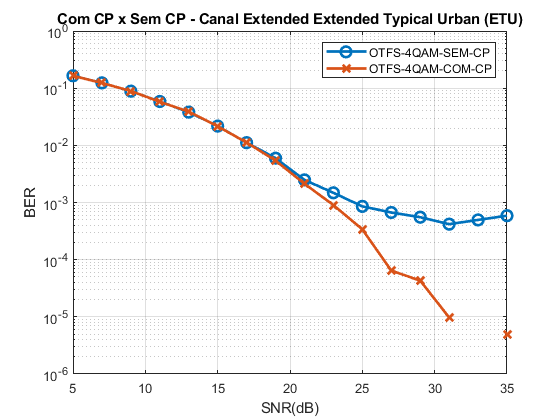


semilogy(snr,meanBER4QAM(1,:),'o-','LineWidth',2,'MarkerSize',8)
hold on;
semilogy(snr,meanBER4QAM(3,:),'x-','LineWidth',2,'MarkerSize',8)
hold on;
grid on
xlabel('SNR(dB)')
ylabel('BER')
title('Com CP x Sem CP - Canal Extended Extended Typical Urban (ETU)')

legend('OTFS-4QAM-SEM-CP', 'OTFS-4QAM-COM-CP');